# Spike Exploration

spikeArtifacts.mlx illustrates specific issues in the analysis of extracellular recordings. This script builds on that to explore some additional parameter dependencies.

## Setup Simulation

Simulation parameters

startup; % Make sure all toolboxes are on the path
clear spkDefaults arDefaults % Avoid lingering values from prevoous runs
spkDefaults.duration                  = 120;    % 2 min
spkDefaults.stimulatorSamplingRate    = 1e3;     % e.g., Starstim (1 kHz)
spkDefaults.currentResolution         = 1e-6;    % 1 muA
spkDefaults.resistance                = 1;        % 1 mA -> 1 mV artifact
spkDefaults.recordingSamplingRate     = 30e3;     % 30kHz
spkDefaults.adcLinearRange            = 6.8e-3;   % Linear range of amplified 6.8 mV
spkDefaults.adcNonlinearity           = 100;      % Piecewise linear
spkDefaults.adcRange                  = 10e-3;     % Input range of the ADC.
spkDefaults.adcBitDepth               = 16;       % Number of bits in the AD convertor
spkDefaults.adcGain                   = 20;       % Amplify 20x
spkDefaults.highPass                  = 0.01;     % High pass filter on the preamp. 
spkDefaults.reproducible              = 2;       % Seed the RNG to get reproducible results

Define the common neural signals

spkDefaults.spikePeak                 = 60e-6;   % 60 muV
spkDefaults.spikeRate                 = 100;      % 100 spk/s
spkDefaults.poisson                           = true;     % Poisson spiking
spkDefaults.fixNrSpikes               = true;     % Deviate from Poisson to get exact firing rate.
spkDefaults.refractoryPeriod          = 1.5e-3;   % 1.5 ms
spkDefaults.additive                  = 20e-6;    % Background activity/noise
spkDefaults.pinkNoise                 = true;     % Pink background noise
spkDefaults.synchrony                 = 0;        % Poisson random spikes, no relation with LFP
spkDefaults.lfpAmplitude              = 0;        % No intrinsic oscillation
spkDefaults.multiplicative            = 0;        % No multiplicative noise


Define the common parameters for artifact removal

arDefaults.slide                     = false;   % No sliding segment
arDefaults.slack                     = 5e-3;    % 5 ms to realign segments
arDefaults.nrSegsPerWindow           = 10;      % 10 segments to average artifact
arDefaults.pcaNr                     = 2;       % First two PC are removed
arDefaults.pcaVarExplained           = Inf;     % Ignore explained variance, always remove 2.
arDefaults.pcaNrSegsPerWindow        = Inf;     % Use all segments (plus the tACS signal; below) to determine basis set.
arDefaults.referenceSegment          = 1;       % Align to first segment
arDefaults.recordingSamplingRate      = spkDefaults.recordingSamplingRate; % Match to the recording

Define the filter that extract signals in the "spike band":

lowCut                      = 500;  % high pass filter cut off
highCut                     = 7000; % Low pass filter cut off.
filterOrder                 = 3; % Filter order  (Butterworth)

## Frequency dependence

The spectral analysis (spikeArtifacts.mlx) shows that the contamination of the spike band depends on the frequency of tACS. Here I investigate how how different tACS frequencies affect the fraction of false negatives (for the current choices of neural signal, noise, and thresholds, the false positive rate is negligible).

methods  =["NOP" "FASTR" "RBAR"];
spk = artSim(spkDefaults);
ar = arDefaults;
spk.tacsAmplitude             = 120e-6;   % A->V artifact
nrMethods = numel(methods);
falsePositive = nan(2,nrTacsFreqs,nrMethods);
falseNegative = nan(2,nrTacsFreqs,nrMethods);
oldState =[];
for m=1:nrMethods
    for i=1:nrTacsFreqs
        spk.tacsFrequency = tacsFreqs(i);
        [~,falsePositive(:,i,m),falseNegative(:,i,m)] = simPlotSpikes(spk,ar,methods(m),lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode,axs=gobjects(4));        
    end
end

********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.233
	 After NOP: MSE = 6.51 muV , r= 1.000
Detected on average 99.8333 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.64e+03 muV , r= 0.230
	 After NOP: MSE =  12 muV , r= 0.999
Detected on average 99.8542 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.226
	 After NOP: MSE = 23.4 muV , r= 0.995
Detected on average 99.8208 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.61e+03 muV , r= 0.226
	 After NOP: MSE = 45.7 muV , r= 0.980
Detected on

ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 17 sec.
	 After FASTR: MSE = 64.1 muV , r= 0.968
Detected on average 99.15 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.64e+03 muV , r= 0.230
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 15 sec.
	 After FASTR: MSE = 64.4 muV , r= 0.967
Detected on average 99.1042 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.226
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 15 sec.
	 After FASTR: MSE = 66.4 muV , r= 0.965
Detected on average 99.1417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.61e+03 muV , r= 0.226
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 15 sec.
	 After FASTR: MSE = 69.8 muV , r= 0.959
Detected on average 99.2042 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.222
Allocating memory...


ans = 0.0195


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 0 min 15 sec.
	 After FASTR: MSE = 81.6 muV , r= 0.932
Detected on average 99.2125 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 2% 
PLV. Sham: 0.00  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.233
	 After RBAR: MSE = 11.8 muV , r= 0.998
Detected on average 99.8375 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE = 1.64e+03 muV , r= 0.230
	 After RBAR: MSE = 5.24 muV , r= 0.999
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.01  tACS: 0.00 
PLV2. Sham: 0.00  tACS: 0.00 
********QC********* 
 Starting Values: MSE 

Generate a figure illustrating the stimuation frequency dependence.

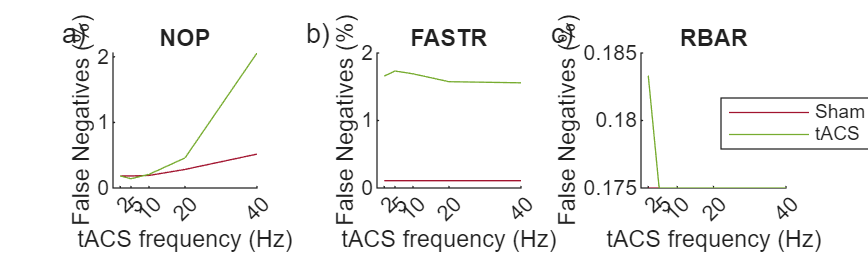

[f,ax] = fig('Name','frequency','paperCols',2,'height',4,'nrRows',1,'nrCols',3);
for method =1:nrMethods
    axes(ax(method))
    hold on
    plot(tacsFreqs,falseNegative(:,:,method)','LineStyle','-');
    xlabel 'tACS frequency (Hz)'
    ylabel 'False Negatives (%)'
    set(gca,'XTick',tacsFreqs);
    title (methods(method))
    
end
legend ('Sham','tACS','Location','south')

## Interactions

The simulations above show a non zero false negative rate after FASTR and that the tACS signal affects the results in the non-tACS trials (due to the shared voltage threshold and waveform clustering procedure). The percentages shown depend on the randomization; to quantify an average effect, I bootstrapped this.

spk = artSim(spkDefaults);
ar = arDefaults;
spk.tacsAmplitude    = 120e-6;   % A->V artifact
spk.tacsFrequency    = 40; % Example frequency
spk.reproducible     = false; % Do not reset the RNG
nrBootstraps = 100;
falseNegFastr= nan(2,nrBootstraps);
% Use a parfor as this takes a while
parfor i=1:nrBootstraps        
    [~,~,falseNegFastr(:,i)] = simPlotSpikes(spk,ar,"FASTR",lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,spikeSortingMode=spikeSortingMode,axs=gobjects(4));        
end

********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.207
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.223
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.245
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.225
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.279
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.359
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.329
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.226
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.255
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.228
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.222
********QC********* 
 Starting Values: MSE = 1.63e+03 muV , r= 0.233
Allocating memory...

ans =

    0.1033


Stage 1 of 2: Slice Alignment
....25% ....50% ....75% ....100%

Stage 2 of 2: Artifact Subtraction
25% 50% FASTR Finished in 2 min

FIgure to show the results.

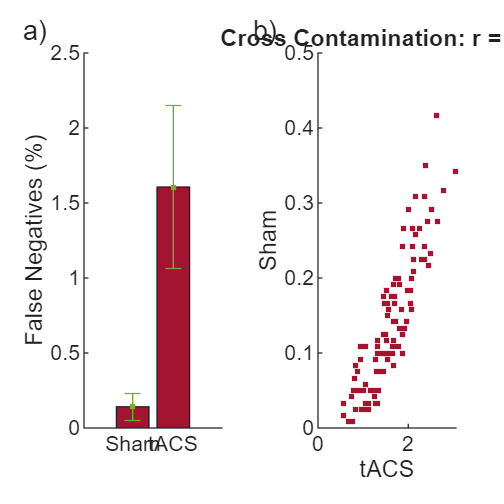

[~,axs] = fig('Name','Interactions','nrRows',1,'nrCols',2);
axes(axs(1))
mFalseNegFastr = mean(falseNegFastr,2,"omitmissing");
sdFalseNegFastr = std(falseNegFastr,0,2,"omitmissing");
bar(mFalseNegFastr);
hold on
errorbar(mFalseNegFastr,sdFalseNegFastr,'.')
set(gca,'XTick',1:2,'XTickLabel',{'Sham','tACS'});
ylabel ('False Negatives (%)');
axes(axs(2))
plot(falseNegFastr(2,:),falseNegFastr(1,:),'.')
xlabel 'tACS'
ylabel 'Sham'
r= corrcoef(falseNegFastr');
title (sprintf('Cross Contamination: r = %.2f',r(1,2)));

## tDCS

Repeat with tDCS and a heartbeat artifact.

spk = artSim(spkDefaults);
ar = arDefaults;
spk.tacsAmplitude    = 0;    % A->V artifact
spk.tdcsMean         = 1e-3;   % A->V artifact

spk.zFun                      = @zHeartbeat;
spk.zAmplitude                = 0.05;
spikeSortingMode                ="ALL";

[~,axs] = fig('Name',"tDCS",'paperCols',2,'height',12,'nrRows',2,'nrCols',2,'byColumn',false);   
[sortResultsNopAll]  = simPlotSpikes(spk,ar,"NOP",xlim = 8+[0 0.1],lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,sharedThreshold = sharedThreshold, spikeSortingMode=spikeSortingMode,axs=[axs(1:2)' gobjects(2)]);

********QC********* 
 Starting Values: MSE = 70.2 muV , r= 0.904
	 After NOP: MSE = 70.2 muV , r= 0.904
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.04  tACS: 0.04 
PLV2. Sham: 0.01  tACS: 0.01 


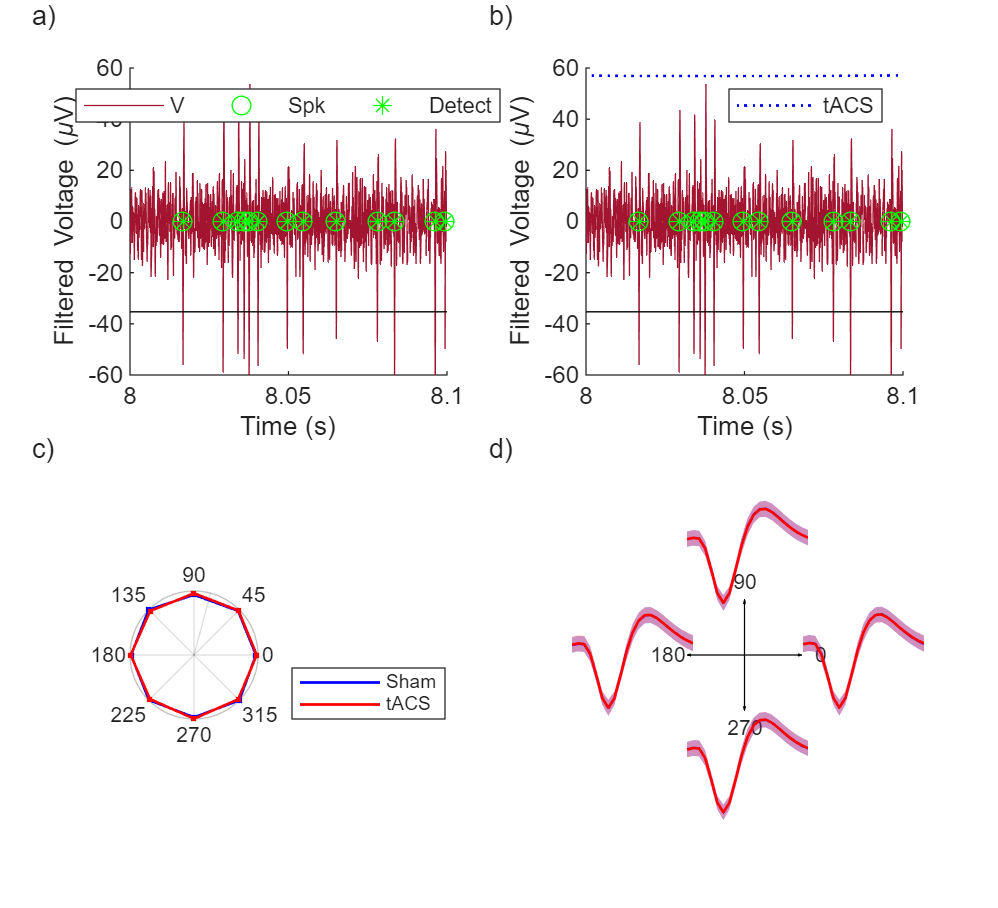

********QC********* 
 Starting Values: MSE = 70.2 muV , r= 0.904
	 After NOP: MSE = 70.2 muV , r= 0.904
Detected on average 99.8417 events per second of data 
False Positive. Sham: 0%  tACS: 0% 
False Negative. Sham: 0%  tACS: 0% 
PLV. Sham: 0.04  tACS: 0.04 
PLV2. Sham: 0.01  tACS: 0.01 


spikeSortingMode                ="MATCHSHAM";
[sortResultsNop]  = simPlotSpikes(spk,ar,"NOP",phaseFromRaw = true,lowCut=lowCut,highCut=highCut,filterOrder=filterOrder,threshold=threshold,sharedThreshold = sharedThreshold, spikeSortingMode=spikeSortingMode,axs=[gobjects(1,2) axs(3:4)]);

The heartbeat artifact does not seem to affect the spike results. Not too surprising given that cardioballistic (and most other physiological artifacts) are low frequency events, far outside the spike band. 